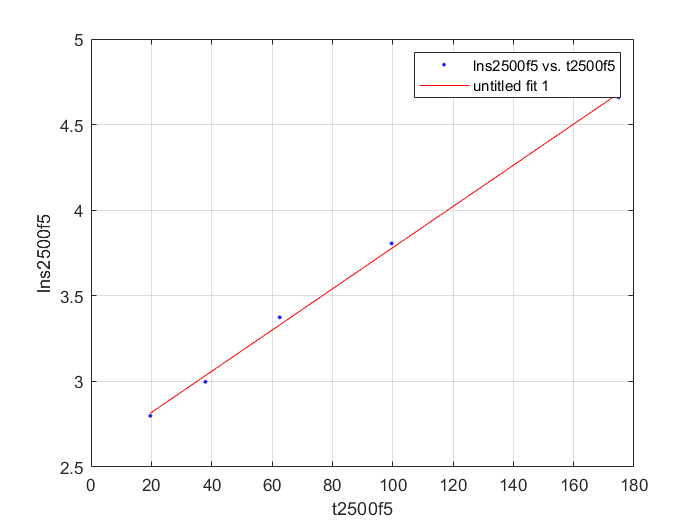

%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( t2500f5, lns2500f5 );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'lns2500f5 vs. t2500f5', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel t2500f5
ylabel lns2500f5
grid on


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =     0.01204  (0.01099, 0.01308)
  %     p2 =       2.577  (2.477, 2.678)

%Goodness of fit:
 % SSE: 0.004859
  %R-square: 0.9978
  %Adjusted R-square: 0.997
  %RMSE: 0.04024